# Marginal cost seasonal regression of selected 4 market participants

## Load cleaned seasonal marginal cost data

load("../model_output/mat_files/cleanedSel4QMCSeasons.mat")
Seasons = ["Spring", "Summer", "Autumn", "Winter"];

## Show distribution of seasonal marginal cost data of 4 selected market participants

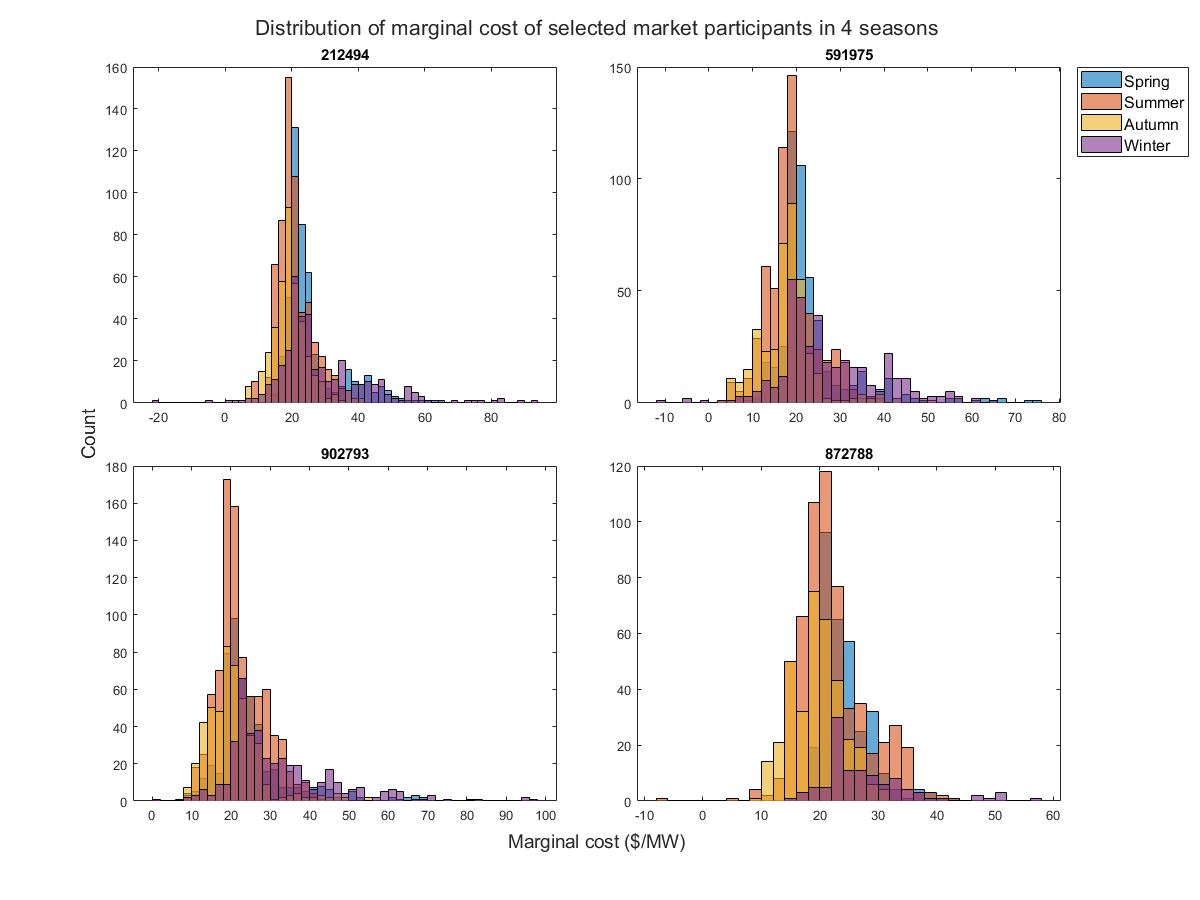

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    hold on;
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        histogram(selQMCOneSeason.MCMarket, "BinWidth", 2);
    end
    hold off; box on;
    title(partID);
    if n==2
        legend(["Spring", "Summer", "Autumn", "Winter"], "Location","bestoutside", "FontSize", 12);
    end    
end
xlabel(t, "Marginal cost ($/MW)", "FontSize", 14);
ylabel(t, "Count", "FontSize", 14);
title(t, "Distribution of marginal cost of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);

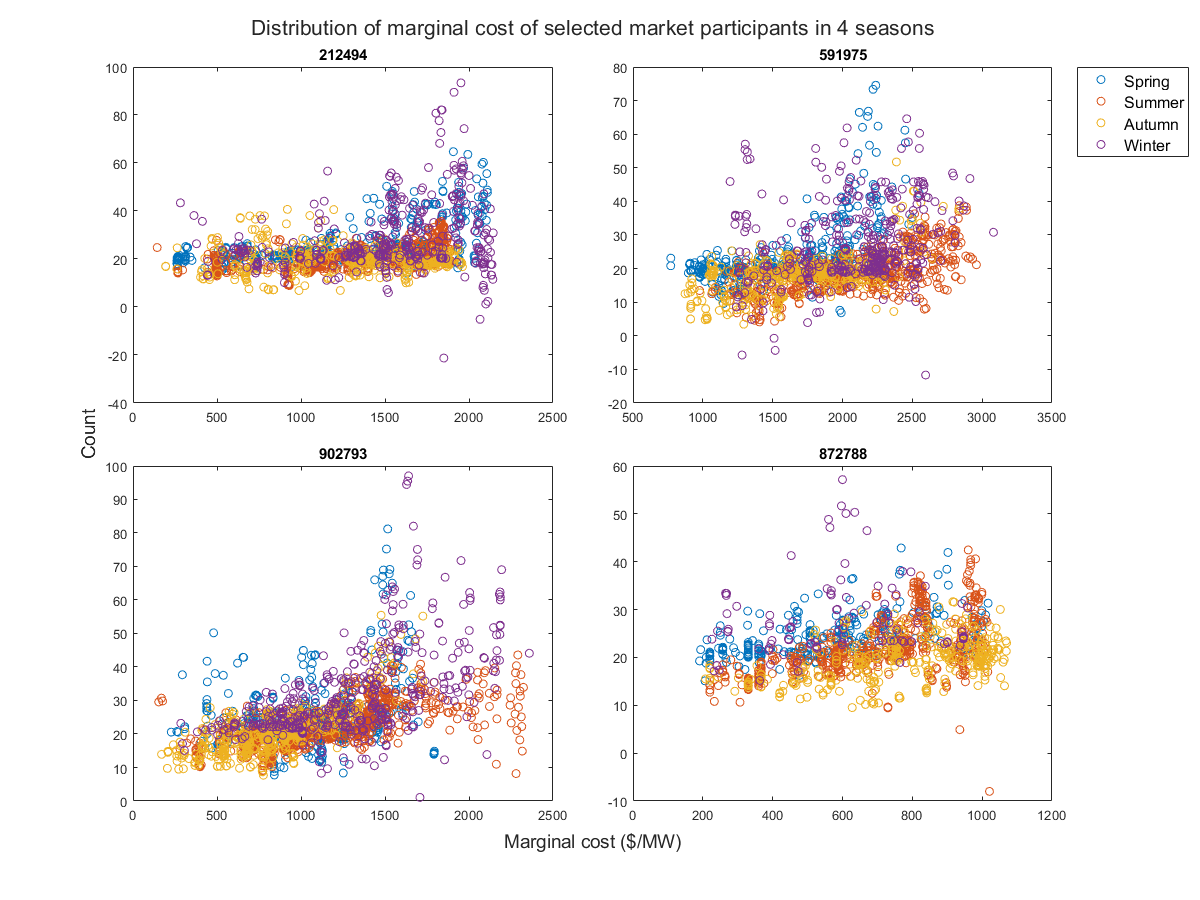

figure;
t = tiledlayout(2,2,"TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    hold on;
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 'o');
    end
    hold off; box on;
    title(partID);
    if n==2
        legend(["Spring", "Summer", "Autumn", "Winter"], "Location","bestoutside", "FontSize", 12);
    end    
end
xlabel(t, "Marginal cost ($/MW)", "FontSize", 14);
ylabel(t, "Count", "FontSize", 14);
title(t, "Distribution of marginal cost of selected market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);

## Fit quadratic relations of marginal cost and quantity

quadQMCSeason = zeros(4, 4, 3);
quadSSeason = cell(4, 4, 1);
quadMuSeason = zeros(4, 4, 2);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        [p, S, mu] = polyfit(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 2);
        [y_fit, delta] = polyval(p, selQMCOneSeason.Awarded, S, mu);
        sel4CleanedQMCSeason{n, s}.MCQuadFit = y_fit;
        sel4CleanedQMCSeason{n, s}.MCQuadDelta = delta;
        sel4CleanedQMCSeason{n, s}.MCQuadError = sel4CleanedQMCSeason{n, s}.MCMarket - sel4CleanedQMCSeason{n, s}.MCQuadFit;
        quadQMCSeason(n, s, :) = p;
        quadSSeason{n, s} = S;
        quadMuSeason(n, s, :) = mu.';
    end
    
end

## Fit cubic relations of marginal cost and quantity

cubicQMCSeason = zeros(4, 4, 4);
cubicSSeason = cell(4, 4, 1);
cubicMuSeason = zeros(4, 4, 2);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        [p, S, mu] = polyfit(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 3);
        [y_fit, delta] = polyval(p, selQMCOneSeason.Awarded, S, mu);
        sel4CleanedQMCSeason{n, s}.MCCubicFit = y_fit;
        sel4CleanedQMCSeason{n, s}.MCCubicDelta = delta;
        sel4CleanedQMCSeason{n, s}.MCCubicError = sel4CleanedQMCSeason{n, s}.MCMarket - sel4CleanedQMCSeason{n, s}.MCCubicFit;
        cubicQMCSeason(n, s, :) = p;
        cubicSSeason{n, s} = S;
        cubicMuSeason(n, s, :) = mu.';
    end    
end

## Visualize quadratic relation

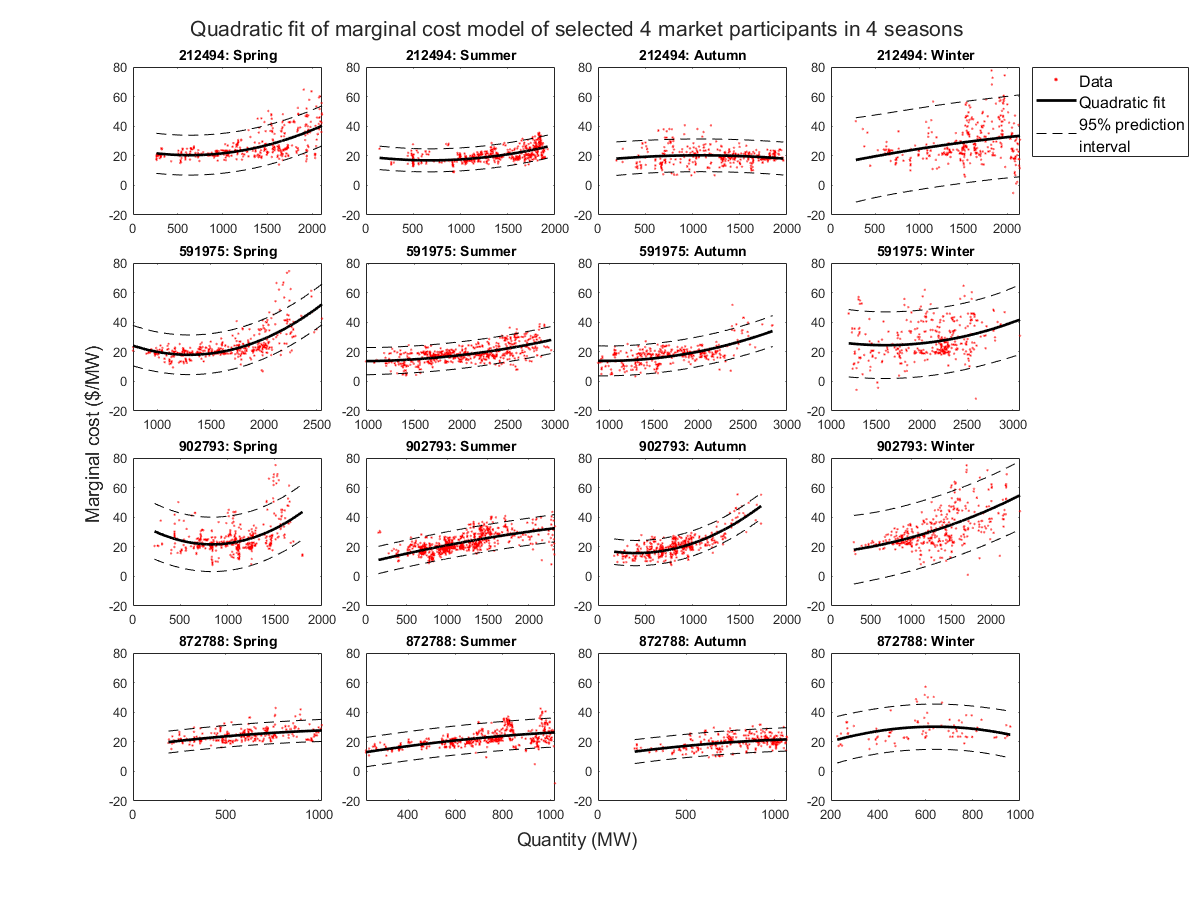

% Plot quantity vs marginal cost of selected market participants
figure;
t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        partID = sel4PartIDs(n);
        Season = Seasons(s);
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Plot cleaned data
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 10, 'r.');
        hold on;
        % Plot quadratic estimation
        plot(selQMCOneSeason.Awarded, selQMCOneSeason.MCQuadFit, 'k-', 'Linewidth', 2);
        quadUpper = selQMCOneSeason.MCQuadFit + 2*selQMCOneSeason.MCQuadDelta;
        quadLower = selQMCOneSeason.MCQuadFit - 2*selQMCOneSeason.MCQuadDelta;
        plot(selQMCOneSeason.Awarded, quadUpper, 'k--', selQMCOneSeason.Awarded, quadLower,'k--');
        title(partID + ": " + Season);
        ylim([-20, 80]);
        hold off; box on;
        if (n==1) && (s==4)
            legend(["Data", "Quadratic fit", "95% prediction\newlineinterval"], "Location","bestoutside", "FontSize", 12);
        end       
    end
end
xlabel(t, "Quantity (MW)", "FontSize", 14);
ylabel(t, "Marginal cost ($/MW)", "FontSize", 14);
title(t, "Quadratic fit of marginal cost model of selected 4 market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/MCQuadFitSeason.png");

## Visualize cubic relation

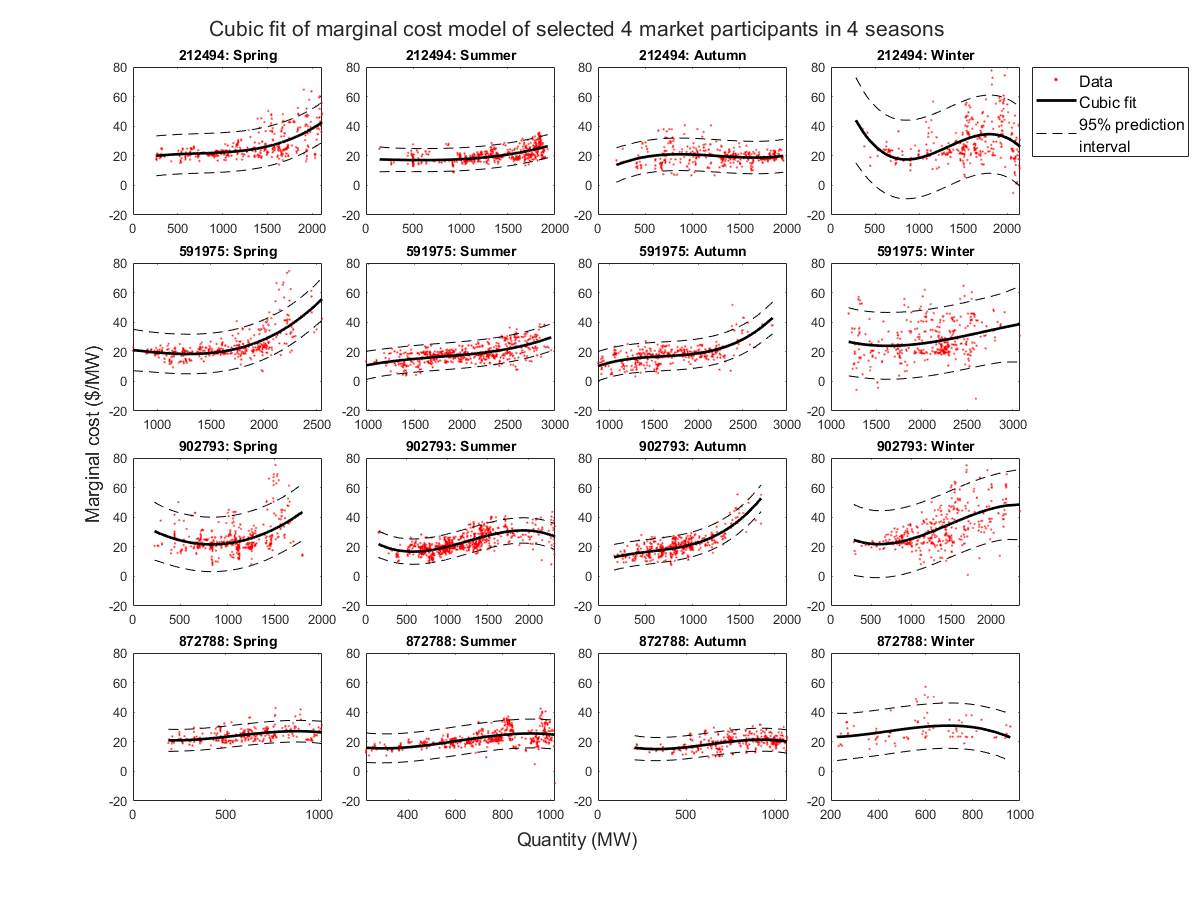

% Plot quantity vs marginal cost of selected market participants
figure;
t = tiledlayout(4, 4, "TileSpacing","compact");
for n=1:4
    for s=1:4
        nexttile;
        partID = sel4PartIDs(n);
        Season = Seasons(s);
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Plot cleaned data
        scatter(selQMCOneSeason.Awarded, selQMCOneSeason.MCMarket, 10, 'r.');
        hold on;
        % Plot quadratic estimation
        plot(selQMCOneSeason.Awarded, selQMCOneSeason.MCCubicFit, 'k-', 'Linewidth', 2);
        quadUpper = selQMCOneSeason.MCCubicFit + 2*selQMCOneSeason.MCCubicDelta;
        quadLower = selQMCOneSeason.MCCubicFit - 2*selQMCOneSeason.MCCubicDelta;
        plot(selQMCOneSeason.Awarded, quadUpper, 'k--', selQMCOneSeason.Awarded, quadLower,'k--');
        title(partID + ": " + Season);
        ylim([-20, 80]);
        hold off; box on;
        if (n==1) && (s==4)
            legend(["Data", "Cubic fit", "95% prediction\newlineinterval"], "Location","bestoutside", "FontSize", 12);
        end       
    end
end
xlabel(t, "Quantity (MW)", "FontSize", 14);
ylabel(t, "Marginal cost ($/MW)", "FontSize", 14);
title(t, "Cubic fit of marginal cost model of selected 4 market participants in 4 seasons", "FontSize", 16);
set(gcf, "Position", [50, 50, 1200, 900]);
saveas(gcf, "../model_output/figures/MCCubicFitSeason.png");

## Show fitness of the quadratic and cubic models

corrQuadSeason = zeros(4, 4, 1);
corrCubicSeason = zeros(4, 4, 1);
RMSEQuadSeason = zeros(4, 4, 1);
RMSECubicSeason = zeros(4, 4, 1);
for n=1:4
    for s=1:4
        selQMCOneSeason = sel4CleanedQMCSeason{n, s};
        % Calculate correlation coefficient
        quadR= corrcoef(selQMCOneSeason.MCMarket, selQMCOneSeason.MCQuadFit);
        cubicR = corrcoef(selQMCOneSeason.MCMarket, selQMCOneSeason.MCCubicFit);
        corrQuadSeason(n, s)= quadR(1, 2);
        corrCubicSeason(n, s) = cubicR(1, 2);
        % Calculate RMSE
        RMSEQuadSeason(n, s) = sqrt(mean(selQMCOneSeason.MCQuadError.^2));
        RMSECubicSeason(n, s) = sqrt(mean(selQMCOneSeason.MCCubicError.^2));
    end  
end
sel4PartIDs = categorical(sel4PartIDs);

### Load annual data fitting results

load("../model_output/mat_files/polyfitCorrRSME.mat")
sel4PartAnnualFit = selPartCorrPolyfit(sel4PartIdx, :)

sel4PartAnnualFit = 4×5 table
    selPartIDs    corrQuad    corrCubic    RMSEQuad    RMSECubic
    __________    ________    _________    ________    _________

      212494      0.41861      0.41983      6.3307      6.3268  
      591975      0.53968      0.53975      4.9817      4.9814  
      902793      0.63816      0.64986      6.3867       6.305  
      872788      0.28343      0.33959      4.5827      4.4947  


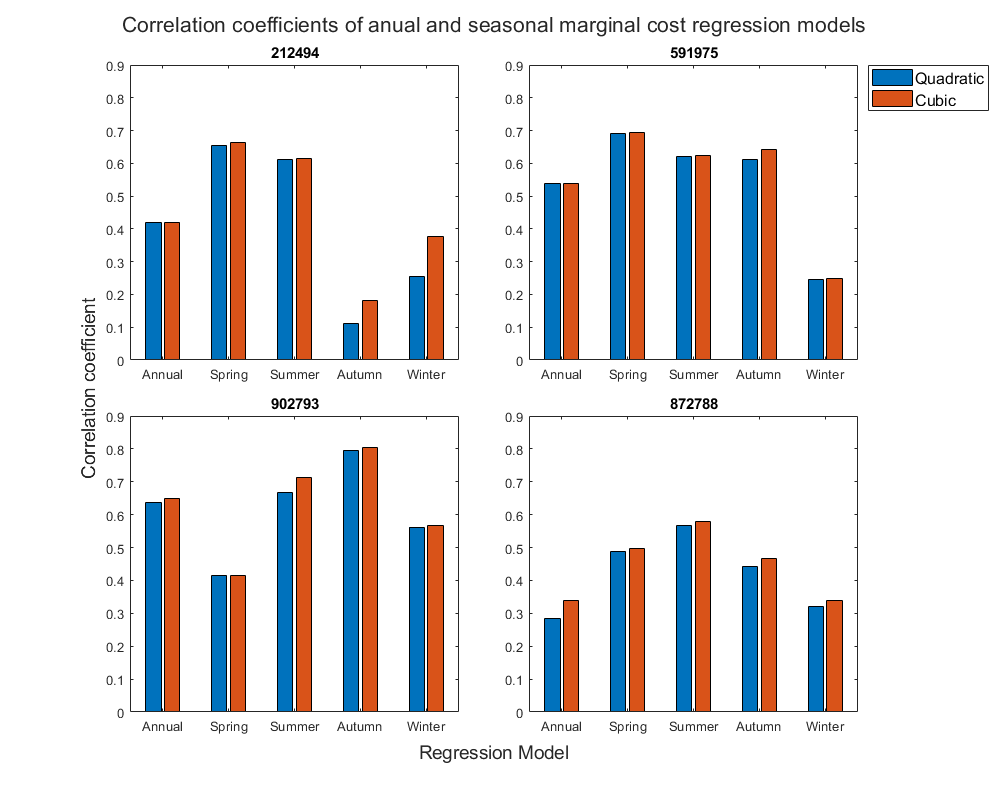

model = categorical(["Annual"; "Spring"; "Summer"; "Autumn"; "Winter"]);
model = reordercats(model, ["Annual"; "Spring"; "Summer"; "Autumn"; "Winter"]);
figure;
t = tiledlayout(2, 2, "TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    anualQuadCorr = sel4PartAnnualFit(n, :).corrQuad;
    anualCubicCorr = sel4PartAnnualFit(n, :).corrCubic;
    seasonalQuadCorr = corrQuadSeason(n, :);
    seasonalCubicCorr = corrCubicSeason(n, :);    
    bar(model, [anualQuadCorr, anualCubicCorr; seasonalQuadCorr', seasonalCubicCorr']);
    title(partID);
    ylim([0, 0.9]);
    if n==2
        legend(["Quadratic", "Cubic"], "Location","bestoutside", "FontSize", 12);
    end
end
xlabel(t, "Regression Model", "FontSize", 14);
ylabel(t, "Correlation coefficient", "FontSize", 14);
title(t, "Correlation coefficients of anual and seasonal marginal cost regression models", "FontSize", 16);
set(gcf, "Position", [50, 50, 1000, 800]);
saveas(gcf, "../model_output/figures/corrCoefPolyfitSeason.png");

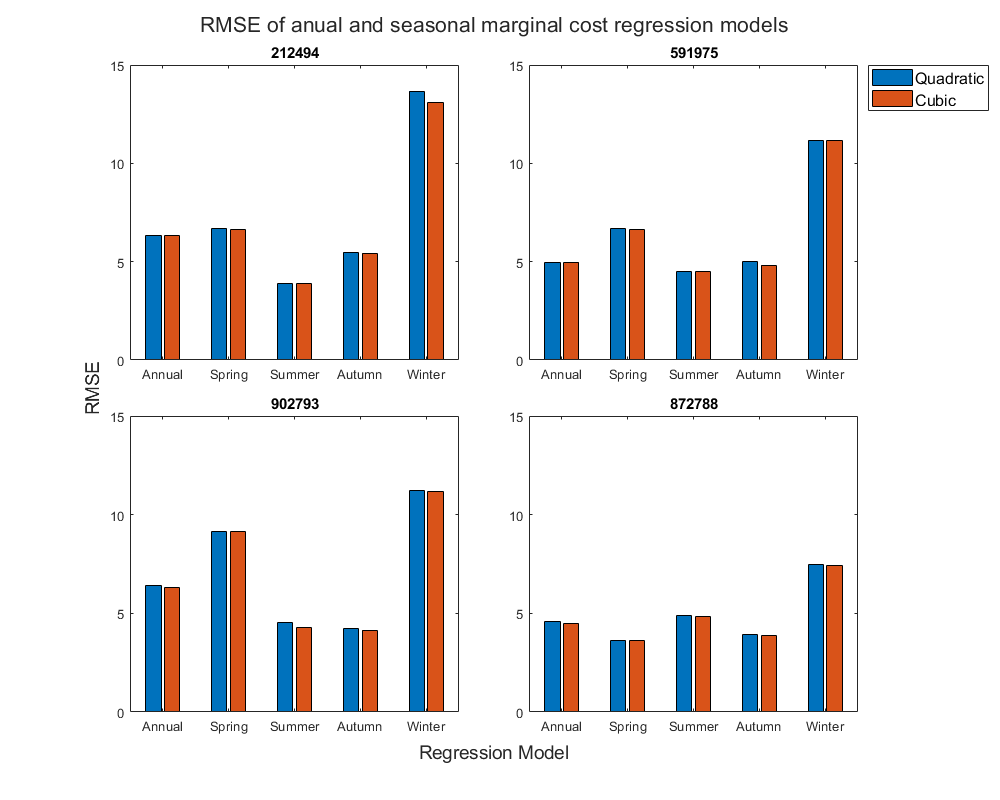

model = categorical(["Annual"; "Spring"; "Summer"; "Autumn"; "Winter"]);
model = reordercats(model, ["Annual"; "Spring"; "Summer"; "Autumn"; "Winter"]);
figure;
t = tiledlayout(2, 2, "TileSpacing","compact");
for n=1:4
    nexttile;
    partID = sel4PartIDs(n);
    anualQuadRMSE = sel4PartAnnualFit(n, :).RMSEQuad;
    anualCubicRMSE = sel4PartAnnualFit(n, :).RMSECubic;
    seasonalQuadRMSE = RMSEQuadSeason(n, :);
    seasonalCubicRMSE = RMSECubicSeason(n, :);    
    bar(model, [anualQuadRMSE, anualCubicRMSE; seasonalQuadRMSE', seasonalCubicRMSE']);
    title(partID);
    ylim([0, 15]);
    if n==2
        legend(["Quadratic", "Cubic"], "Location","bestoutside", "FontSize", 12);
    end
end
xlabel(t, "Regression Model", "FontSize", 14);
ylabel(t, "RMSE", "FontSize", 14);
title(t, "RMSE of anual and seasonal marginal cost regression models", "FontSize", 16);
set(gcf, "Position", [50, 50, 1000, 800]);
saveas(gcf, "../model_output/figures/RMSEPolyfitSeason.png");

## Write fitted models to file

sel4PolyFitQMCSeason = sel4CleanedQMCSeason;
save("../model_output/mat_files/MCQuadFitSeason.mat", "quadQMCSeason", "quadSSeason", "quadMuSeason", "-mat");
save("../model_output/mat_files/MCCubicFitSeason.mat", "cubicQMCSeason", "cubicSSeason", "cubicMuSeason", "-mat");
save("../model_output/mat_files/MCSeasonFitResults.mat", "sel4PolyFitQMCSeason", "sel4PartIdx", "sel4PartIDs", "-mat");